# Classifing ECGs using neural networks on your laptop

This code will use a pretrained neural network to classify ECGs using your personal laptop. The code is divided into two sections that you will run to answer the questions in the PSS. T*his is based on a Matlab example based on electrocardiogram (ECG) data from the PhysioNet 2017 Challenge. You can find that larger example here: *[*Classify ECG Signals Using Long Short-Term Memory Networks with GPU Acceleration*](docid:signal_ug#mw_69d369a4-47bb-4046-b15c-da960df11f28)*. If you are interested in using the GT AI Makerspace cluster to explore the larger example please reach out to Dr. Todd Fernandez in the BME department*

# **Major Note **You should run this code in SECTIONS 

meaning in the **live editor toolbar** you need to use **RUN SECTION ****not RUN.** . Each code sectino will out put information that you need to answer the questions on the PSS worksheet. 

## *Section 1: Load data, configure data, display ECGs (PSS Problem 1.A and 1.B)*

*This section loads all of the files you need and will display several ECGs that you will use to do manual diagnostics of ECG signals*

### Load Data

this section loads all the variables you will need and does basic configuration

clear all
clc

%load everything we need
load PhysionetData
load net

[Signals,Labels] = segmentSignals(Signals,Labels);

afibX = Signals(Labels=='A');
afibY = Labels(Labels=='A');

normalX = Signals(Labels=='N');
normalY = Labels(Labels=='N');

The code below summarizes the 'labels' - meaning it tells you how many AFib and how many normal signals there are. The ratio is about 7:1 Not AFib to AFib, which means there are far fewer AFib signals. This will come into play in a minute.

summary(Labels)

     A       718 
     N      4937 


### Setup data

This section divides the data into equal test and training data sets

rng("default")
[trainIndA,testIndA] = dividerand(length(afibX),0.8,0.1,0.1);
[trainIndN,testIndN] = dividerand(length(normalX),0.8,0.1,0.1);
XTrainA = afibX(trainIndA);
YTrainA = afibY(trainIndA);
XTrainN = normalX(trainIndN);
YTrainN = normalY(trainIndN);

XTestA = afibX(testIndA);
YTestA = afibY(testIndA);
XTestN = normalX(testIndN);
YTestN = normalY(testIndN);

The dataset is imbalanced. To achieve a similar number of AFib and Normal signals, repeat the AFib signals seven times. This is important to prevent bias. If we did not do this, the model could achieve 87% acuracy just by blindly classifying every signal as not AFib. This is a common problem in diagnostic testing...if the thing you are testing for is rare in your population, high accuracy is driven primarily by negative test results.

XTrain = [repmat(XTrainA,7,1); XTrainN];
YTrain = [repmat(YTrainA,7,1); YTrainN];

XTest = [repmat(XTestA,7,1); XTestN];
YTest = [repmat(YTestA,7,1); YTestN];


### Print  ECGs for diagnostics

This code generates three plots of ECG signals. The first plot is the same for everyone, the other two are random. 

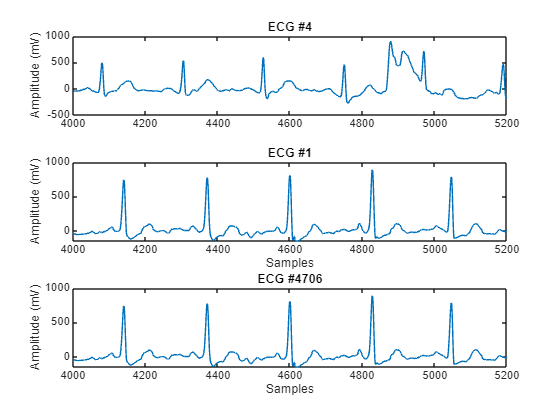

rand_1 = 4;
rand_2 = 1;
rand_3 = randi(length(Labels));


ecg_1 = Signals{4};
ecg_2 = Signals{1};
ecg_3 = Signals{rand_2};

subplot(3,1,1)
    plot(-ecg_1)
    title(sprintf('ECG #%d',rand_1))
    xlim([4000,5200])
    ylabel('Amplitude (mV)')
subplot(3,1,2)
    plot(ecg_2)
    title(sprintf('ECG #%d',rand_2))
    xlim([4000,5200])
    xlabel('Samples')
    ylabel('Amplitude (mV)')
subplot(3,1,3)
    plot(ecg_3)
    title(sprintf('ECG #%d',rand_3))
    xlim([4000,5200])
    xlabel('Samples')
    ylabel('Amplitude (mV)')

## *Section 2a (if you have Matlab 2024 run this): Visualize and discuss AI model accuracy (PSS Problem 1.E)*

This section of code generates a plot of how accurate the neural network is at identifying Atrial Fibulation in a TEST data set - meaning how accurate is it when given NEW data on the same phenomenon. It will output a confusion matrix (which compares the actual classification of the data to the predicted classification), an overall accuracy calculation, and an inference time).

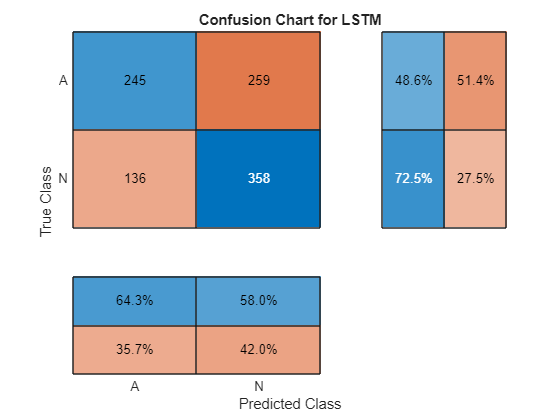

tic;
classNames = categories(YTrain);
scores = minibatchpredict(net,XTest,InputDataFormats="CTB");
testPred = scores2label(scores,classNames);
inference_time = toc;
Train_Accuracy = sum(testPred == YTest)/numel(YTest)*100;
figure
confusionchart(YTest,testPred,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title','Confusion Chart for LSTM');

inference_time

inference_time = 49.5210

Train_Accuracy

Train_Accuracy = 60.4208

## *Section 2b (if you have Matlab 2023 OR EARLIER run this): Visualize and discuss AI model accuracy (PSS Problem 1.E)*

This section of code generates a plot of how accurate the neural network is at identifying Atrial Fibulation in a TEST data set - meaning how accurate is it when given NEW data on the same phenomenon. It will output a confusion matrix (which compares the actual classification of the data to the predicted classification), an overall accuracy calculation, and an inference time).

tic;
[testPred_labels,testPred_probabilities] = Predict_3100(net,XTest,YTest);
inference_time = toc;
Train_Accuracy = sum(testPred == YTest)/numel(YTest)*100;
figure
confusionchart(YTest,testPred,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title','Confusion Chart for LSTM');
inference_time
Train_Accuracy